## **1. Denoising and Filtering**

(a) The input files are given as “speech.wav” and “noise.wav”. You should use function **audioread **to read the time-domain signal and the sampling frequency Fs. 

clear

[speech, Fs] = audioread("speech.wav");
[noise, Fs_noise] = audioread("noise.wav");

(b) Add noise to the speech signal. Plot the original speech signal and noised speech signal in time domain as a waveform and frequency domain as its amplitude spectrum respectively.

Hint: The x-axis of the time domain waveform should be in seconds (s), which means that you need to calculate the corresponding time of each sampling point on the timeline first. For the frequency domain, you should give the amplitude as the y-axis and concrete frequency (Hz) from 0 to Fs/2 as the x-axis. You can use function fft() and abs() to get the N-point DFT of the signal.

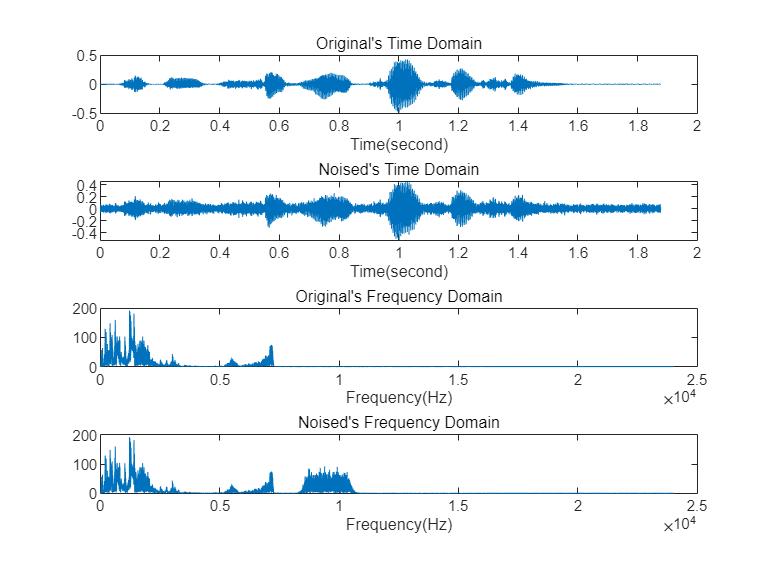

% Add noise to the speech signal.
Noised = noise + speech;


%sound(noised_speech, Fs);


% get_time_domain
[x1_speech, y1_speech] = get_time_domain(speech, Fs);
[x1_Noised, y1_Noised] = get_time_domain(Noised, Fs);


% get_frequency_domain
[x2_speech, y2_speech] = get_frequency_domain(speech, Fs);
[x2_Noised, y2_Noised] = get_frequency_domain(Noised, Fs);

% go to the "My fucntions" at the EOF for the source code of these two functions 


% show the graphs.
figure
subplot(4, 1, 1);
plot(x1_speech, y1_speech), 
title("Original's Time Domain")
xlabel("Time(second)")

subplot(4, 1, 2);
plot(x1_Noised, y1_Noised)
title("Noised's Time Domain")
xlabel("Time(second)")

subplot(4, 1, 3);
plot(x2_speech, y2_speech)
title("Original's Frequency Domain")
xlabel("Frequency(Hz)")

subplot(4, 1, 4);
plot(x2_Noised, y2_Noised)
title("Noised's Frequency Domain")
xlabel("Frequency(Hz)")

(c) The sound will be reflected back when it encounters an object in the transmission, and the auditory effect is like the echo of your shout in the valley. It is not difficult to understand that it is caused by the mixture of the original signal and the reflected signal. Therefore, the model of echo mixing can be expressed as follows:


$$y\left(t\right)=x\left(t\right)+\alpha *x\left(t-T_0 \right)$$



$$y\left(n\right)=x\left(n\right)+\alpha *x\left(n-N_0 \right)$$
                                  

Try to add echo to the noised speech signal from b). The echo is added after 1s, and the attenuation coefficient of the echo is 0.2 ($T_0 =1,\;\alpha =0\ldotp 2,\;N_0 =T_0 *F_s$). Plot the noised speech signal with echo in time domain as a waveform and frequency domain as its amplitude spectrum respectively.

Hint: You can add zeros before the start of the signal to get the echo. At the same time, the length of the signal will change by adding echo.

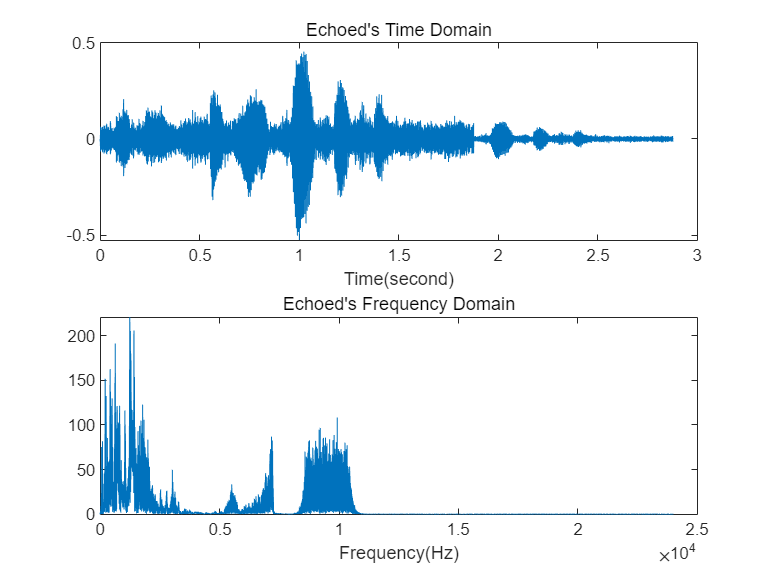

% set Coefficients
Aplha = 0.2;
T0 = 1;
N0 = T0 * Fs;

% bulid a empty container for the new echoed sound
Echoed = zeros(size(Noised, 1) + N0, 1);

% add the echo
Echoed(N0 + 1 : end) = Aplha * (Noised);

% add the original
Echoed(1:length(Noised)) = Echoed(1:length(Noised)) + Noised;


%sound(echoed_speech, Fs);


% get_time_domain
[x1_Echoed, y1_Echoed] = get_time_domain(Echoed, Fs);

% get_frequency_domain
[x2_Echoed, y2_Echoed] = get_frequency_domain(Echoed, Fs);

% go to the "My fucntions" at the EOF for the source code of these two functions 


% show the graphs.
figure
subplot(2, 1, 1);
plot(x1_Echoed, y1_Echoed), 
title("Echoed's Time Domain"),
xlabel("Time(second)")

subplot(2, 1, 2);
plot(x2_Echoed, y2_Echoed)
title("Echoed's Frequency Domain")
xlabel("Frequency(Hz)")

(d) Remove the echo by inverse filtering. The Z-transform converts a discrete-time signal into a complex frequency-domain. 


$$y\left(n\right)=x\left(n\right)+\alpha *x\left(n-N_0 \right)$$



$$y\left(n\right)\iff Y\left(z\right)\;\;\;\;$$

$$x\left(n\right)\iff X\left(z\right)$$



$$Y\left(z\right)=\left(1+\alpha *z^{-N_0 } \right)X\left(z\right)=H\left(z\right)X\left(z\right)$$



$$\;\;\;\;H\left(z\right)=1+\alpha *z^{-N_0 }$$


Therefore, echo mixing can be regarded as the generation of signal  after passing through $H\left(z\right)$. Then removing the echo can be realized by inverse filtering, and the inverse system of $H\left(z\right)$ is


$$H^{-1} \left(z\right)=\frac{1}{1+\alpha *z^{-N_0 } }$$


You can use function **filter **to implement inverse filtering as follow:

$b=\left\lbrack 1\right\rbrack ;a=\left\lbrack 1,\textrm{zeros}\left(1,N_0 -1\right),\alpha \right\rbrack$;


$$x=\textrm{filter}\left(b,a,y\right);$$


Try to implement inverse filtering to the noised speech signal with echo from c) to remove the echo. Plot the signal before and after the inverse filtering in time domain as a waveform respectively. 

Hint: You can use function** sound** to play the speech signal to verify whether the elimination of echo is successful

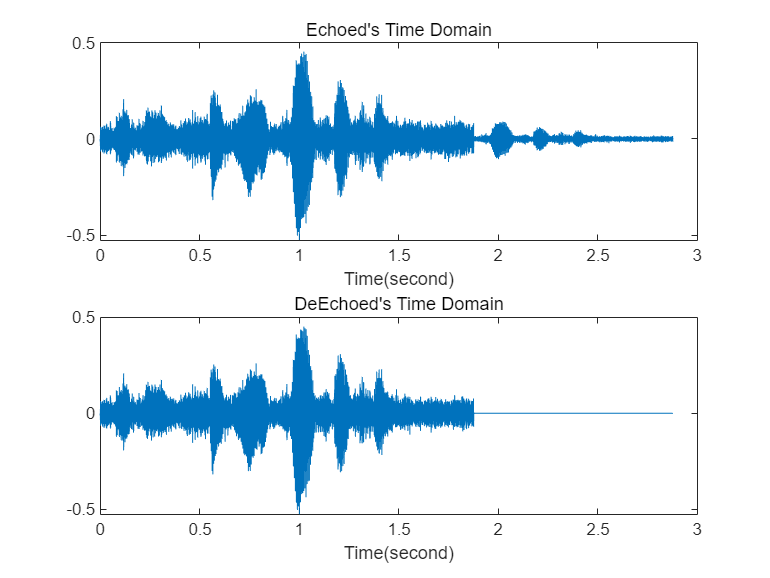

b = 1;
a = [b, zeros(1,N0 - 1), Aplha];

DeEchoed = filter(b, a, Echoed);


%sound(Echoed, Fs);


% get_time_domain
[x1_DeEchoed, y1_DeEchoed] = get_time_domain(DeEchoed, Fs);

% get_frequency_domain
[x2_DeEchoed, y2_DeEchoed] = get_frequency_domain(DeEchoed, Fs);

% go to the "My fucntions" at the EOF for the source code of these two functions 


% show the graphs.
figure
subplot(2, 1, 1);
plot(x1_Echoed, y1_Echoed), 
title("Echoed's Time Domain"),
xlabel("Time(second)")

subplot(2, 1, 2)
plot(x1_DeEchoed, y1_DeEchoed)
title("DeEchoed's Time Domain"),
xlabel("Time(second)")

(e) Design a FIR filter use **fdatool** command and filter the noised speech signal without echo from d) with function filter to remove the noise. You are required to declare the filter type you used and briefly explain the design parameters you choose. You are then required to plot: (1) The magnitude response of the filter in frequency domain; (2) The noised speech signal without echo from d) and the filtered signal in time domain as a waveform and frequency domain as its amplitude spectrum respectively.

Hint: You can also use function **sound** to play the speech signal to verify whether the elimination of noise is successful

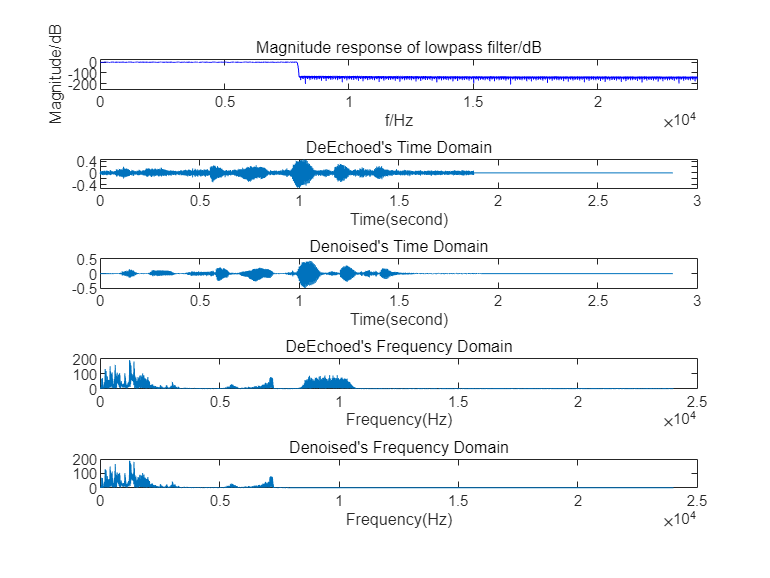

% declare the filter type you used and briefly explain the design parameters you choose 

Hd = noise_cancellation_filter;  
% Tpye = lowpass
% Fpass = 7900
% Fstop = 8000
% Apass = 1
% Astop = 200
% go to the "My fucntions" at the EOF for the complete details 

Denoised = filter(Hd, DeEchoed);


%sound(Denoised, Fs)


% code from Tutorial
Hd = noise_cancellation_filter; % load the filter (correspond to the filename)
[H,w]=freqz(Hd); % use funciton freqz to plot the magnitude response of lowpass filter 
dbH=20*log10(abs(H)/max(abs(H))); % set y-axis in dB 


% get_time_domain
[x1_Denoised, y1_Denoised] = get_time_domain(Denoised, Fs);

% get_frequency_domain
[x2_Denoised, y2_Denoised] = get_frequency_domain(Denoised, Fs);

% go to the "My fucntions" at the EOF for the source code of these two functions 


% show the graphs
figure
subplot(5, 1, 1)
plot(w * Fs/(2 * pi), dbH, 'b'); 
axis([0 Fs/2 -250 25]); %Set the display range of the axis
title('Magnitude response of lowpass filter/dB');
xlabel('f/Hz');ylabel('Magnitude/dB')

subplot(5, 1, 2)
plot(x1_DeEchoed, y1_DeEchoed)
title("DeEchoed's Time Domain")
xlabel("Time(second)")

subplot(5, 1, 3)
plot(x1_Denoised, y1_Denoised)
title("Denoised's Time Domain")
xlabel("Time(second)")

subplot(5, 1, 4)
plot(x2_DeEchoed, y2_DeEchoed)
title("DeEchoed's Frequency Domain")
xlabel("Frequency(Hz)")

subplot(5, 1, 5)
plot(x2_Denoised, y2_Denoised)
title("Denoised's Frequency Domain")
xlabel("Frequency(Hz)")

## 2. **Audio Signal Processing **

(a)The input file is given as “handel.wav”. You should use function **audioread **to read the time-domain signal and the sampling frequency Fs. 

clear

[music, Fs] = audioread("handel.wav");

(b)Plot the signal in time domain as a waveform and frequency domain as its amplitude spectrum. The x-axis of the time domain waveform should be in seconds (s). For the frequency domain, you should give the amplitude as the y-axis and concrete frequency (Hz) from 0 to Fs/2 as the x-axis. You can first use function **fft() **and** abs()** to get the N-point DFT of the signal.

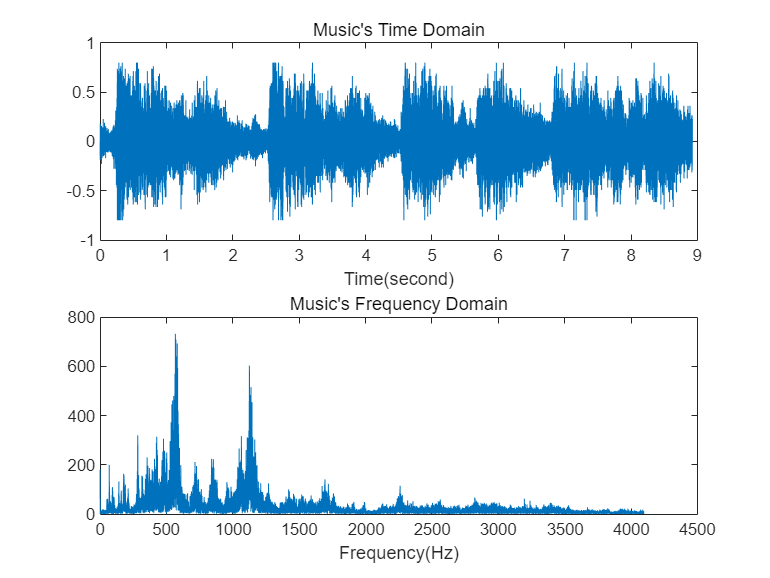

% get_time_domain
[x1_spliced, y1_spliced] = get_time_domain(music, Fs);

% get_frequency_domain
[x2_music, y2_music] = get_frequency_domain(music, Fs);

% go to the "My fucntions" at the EOF for the source code of these two functions 


% show the graphs
figure
subplot(2, 1, 1);
plot(x1_spliced, y1_spliced)
title("Music's Time Domain")
xlabel("Time(second)")

subplot(2, 1, 2);
plot(x2_music, y2_music)
title("Music's Frequency Domain")
xlabel("Frequency(Hz)")

(c)Make a simple equalizer. The equalizer allocates different weights various different frequency bandwidth. This can be realized by a couple of band-pass filters. In this case, eight filters are adopted for 32, 64, 125, 250, 500, 1k, 2k and 4kHz. Design the filters as you prefer and splice the signals filtered by your filters. Before filtering, consider the following questions. What is the filter type you choose? Is it time-domain or frequency domain? Is it IIR or FIR filter? What is the reason that you choose it? After that, Plot the spectrum of the difference of the original signal and filtered signal. (The difference should be minimized as far as possible, which is your task.)

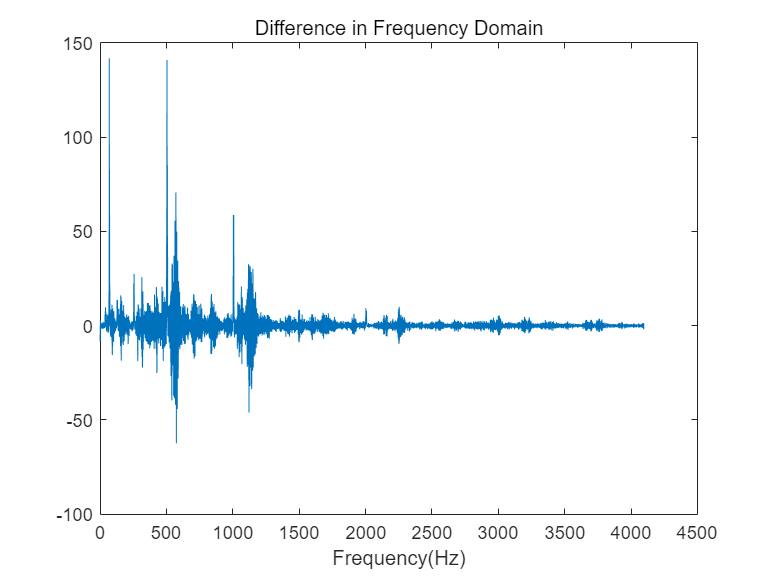

% Since 8 filters are quite many, I'm not going to show their source code 
% in this PDF


% filter 8 bands
slice(:,1) = filter(fir32, music);
slice(:,2) = filter(fir64, music);
slice(:,3) = filter(fir125, music);
slice(:,4) = filter(fir250, music);
slice(:,5) = filter(fir500, music);
slice(:,6) = filter(fir1000, music);
slice(:,7) = filter(fir2000, music);
slice(:,8) = filter(fir4000, music);


% spliced 8 bands back
spliced = zeros(length(music),1);
for i = 1:8 
    spliced = spliced + slice(:,i);
end


%sound(spliced, Fs)
%sound(music, Fs)


% get_frequency_domain
[x2_music, y2_music] = get_frequency_domain(music, Fs);
[x2_spliced, y2_spliced] = get_frequency_domain(spliced, Fs);

% get the difference
x_difference = x2_music;
y_difference = y2_music - y2_spliced;


% go to the "My fucntions" at the EOF for the source code of these two functions 


% show the graphs
figure
plot(x_difference, y_difference)
title("Difference in Frequency Domain")
xlabel("Frequency(Hz)")

(d)Assign weights for each filter to make the voice of human clearer. The values of weights can range from -12dB to 12dB. Plot the spectrum of the filtered signals again and save it through function **audiowrite**. 

Hint: dB is a parameter describing gain. $G\left(w\right)=20\log_{10} \left(\left|H\left(e^{\textrm{jw}} \right)\right|\right)$

% set the weights
e(1) = -3;  % 32Hz
e(2) = -3;  % 64Hz
e(3) = 0;   % 125Hz
e(4) = 0;   % 250Hz
e(5) = 4;   % 500Hz
e(6) = -5;  % 1KHz
e(7) = 5;   % 2KHz
e(8) = 0;   % 4KHz


% spliced 8 bands back
equalized = zeros(length(music),1);
for i = 1:8 
    equalized_slice(:,i) = slice(:,i) .* 10^(e(i)/20);
    equalized = equalized + equalized_slice(:,i);
end


%sound(equalized, Fs)


audiowrite("equalized_handle.wav", equalized, Fs);

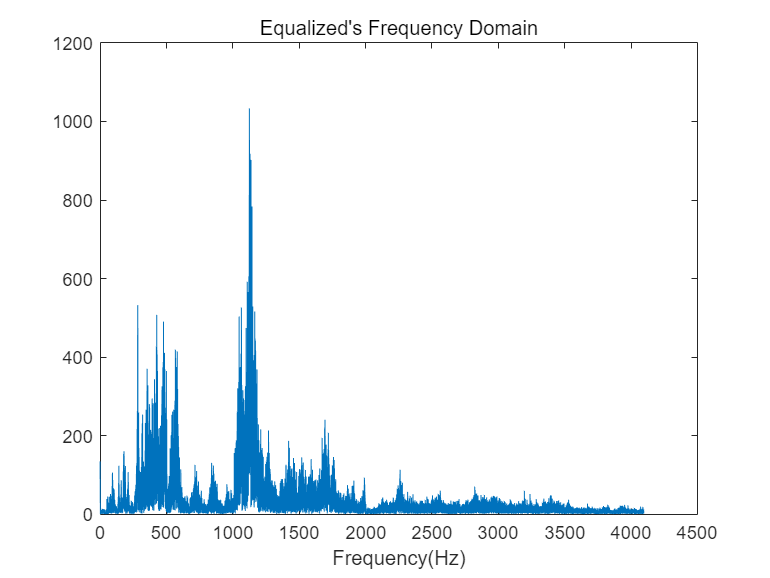



% get_frequency_domain
[x2_equalized, y2_equalized] = get_frequency_domain(equalized, Fs);

% go to the "My fucntions" at the EOF for the source code of these two functions 


% show the graphs
figure
plot(x2_equalized, y2_equalized)
title("Equalized's Frequency Domain")
xlabel("Frequency(Hz)")

(e)Implement the voice transferring (voice to the opposite gender). Use function **resample **to try it. However, there may be two problems. When we upsample the audio, we need to drop out weak signals. When we downsample the audio, we need to padding to maintain the length of the audio. Plot the time-domain sequence and Fourier spectrum before and after the voice transferring. 

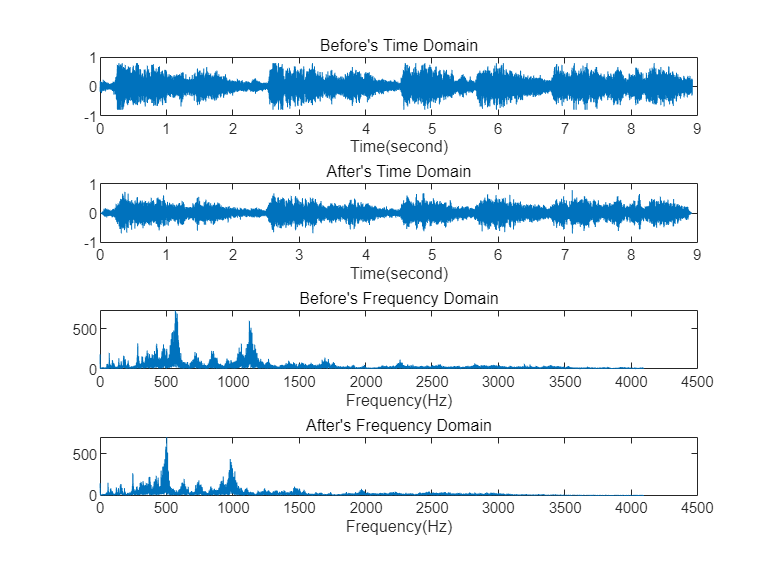

clear

[before, Fs] = audioread("handel.wav");


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% downsample
p = 7200;
q = Fs;

y = resample(before, p, q);
stretched_y = stretchAudio(y, p / q);

%sound(stretched_y, Fs)
%pause(9)


% padding(recover the downsampled audio)
l = length(y);

x = 1: 1: l; 
xi = 1: (p / q): l;
y = interp1(x, y, xi);

%sound(y, Fs)
%pause(9)


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% upsample !(gender transform)!
p = 9400;
q = Fs;

after = resample(before, p, q);
stretched_after = stretchAudio(after, p / q);

%sound(stretched_after, Fs)
%pause(9)


% drop out weak signals(recover the upsampled audio)
l = length(after);
    
x = 1: 1: l; 
xi = 1: (p / q): l;
z = interp1(x, after, xi);

%sound(z, Fs)
%pause(9)


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% get_time_domain
[x1_before, y1_before] = get_time_domain(before, Fs);
[x1_after, y1_after] = get_time_domain(stretched_after, Fs);


% get_frequency_domain
[x2_before, y2_before] = get_frequency_domain(before, Fs);
[x2_after, y2_after] = get_frequency_domain(stretched_after, Fs);

% go to the "My fucntions" at the EOF for the source code of these two functions 


% show the graphs.
figure
subplot(4, 1, 1);
plot(x1_before, y1_before), 
title("Before's Time Domain")
xlabel("Time(second)")

subplot(4, 1, 2);
plot(x1_after, y1_after)
title("After's Time Domain")
xlabel("Time(second)")

subplot(4, 1, 3);
plot(x2_before, y2_before)
title("Before's Frequency Domain")
xlabel("Frequency(Hz)")

subplot(4, 1, 4);
plot(x2_after, y2_after)
title("After's Frequency Domain")
xlabel("Frequency(Hz)")

# **My functions:**

**1)get_time_domain**

function [x, y] = get_time_domain(audio, Fs) 
       
    x = (1 : length(audio))*(1 / Fs);   
    % transform the unit of time-domain's x-axis.   
    
    y = audio;

end

**2)get_frequency_domain**

function [x, y] = get_frequency_domain(audio, Fs) 

    stgram = abs(fft(audio));

    x = (1 : int64(length(audio) / 2)) * (Fs / length(audio));   
    % transform the unit of frequency-domain's x-axis.   
    
    y = stgram(1 : int64(length(audio)/2), 1);

end

**3)noise_cancellation_filter**

function Hd = noise_cancellation_filter
%ASD 返回离散时间滤波器对象。

% MATLAB Code
% Generated by MATLAB(R) 9.12 and DSP System Toolbox 9.14.
% Generated on: 27-Nov-2022 17:01:38

% Equiripple Lowpass filter designed using the FIRPM function.

% All frequency values are in Hz.
Fs = 48000;  % Sampling Frequency

Fpass = 7900;            % Passband Frequency
Fstop = 8000;            % Stopband Frequency
Dpass = 0.057501127785;  % Passband Ripple
Dstop = 1e-10;           % Stopband Attenuation
dens  = 20;              % Density Factor

% Calculate the order from the parameters using FIRPMORD.
[N, Fo, Ao, W] = firpmord([Fpass, Fstop]/(Fs/2), [1 0], [Dpass, Dstop]);

% Calculate the coefficients using the FIRPM function.
b  = firpm(N, Fo, Ao, W, {dens});
Hd = dfilt.dffir(b);

% [EOF]
end